## Model linearisation

% Model linearisation
step_size = 1e-4; 
u = 20;  % velocity to linearise about 
[theta_LR, theta_UR, theta_1s, theta_1c, phi, theta, delta_E, delta_R] = F_fsolve(u);
state = [u, 0, 0, 0, 0, 0, phi, theta, 0];
ctrl = [theta_LR, theta_UR, theta_1s, theta_1c, delta_E, delta_R];

% average mass, CG and moment of inertia during patient transport
params = [1524, 2630.668, 9.80665, 0.52992, 0.682, 0.682, 5.5, 5.5];

% for linearisation
theta_0 = 0.5 * (theta_LR + theta_UR);
theta_diff = 0.5 * (theta_UR - theta_LR);
ctrl_trans = [theta_0, theta_diff, theta_1s, theta_1c, delta_E, delta_R];

% Make sure this is very close to 0 so we are trim the helicopter
xdot = stateDerivative(state, ctrl_trans, params)

[A, B, A_lon, B_lon, A_lat, B_lat] = Linearisation(state, ctrl, params, stepsize)

## State-space objects

% Define C and D matrices for attitude and velocity
C_long_att = [0 0 0 1];  % output theta for longitudinal attitude controller
C_lat_att = [0 0 0 1 0;
             0 0 0 0 1];  % output phi & psi for lateral attitude controller
D_long_att = [0 0 0];
D_lat_att = [0 0 0;
             0 0 0];

% Velocity matrices
C_long_vel = [1 0 0 0;
              0 1 0 0];  % output u & w
C_lat_vel = [1 0 0 0 0];  % output v
D_long_vel = [0 0 0;
              0 0 0];
D_lat_vel = [0 0 0];

% attitude ss
ss_long_att = ss(A_lon, B_lon, C_long_att, D_long_att);
ss_lat_att = ss(A_lat, B_lat, C_lat_att, D_lat_att);

% velocity ss
ss_long_vel = ss(A_lon, B_lon, C_long_vel, D_long_vel);
ss_lat_vel = ss(A_lat, B_lat, C_lat_vel, D_lat_vel);

% adjusting state names
ss_long_att.StateName = {'u-vel'; 'w-vel'; 'pitch rate';
  'pitch angle'};
ss_long_vel.StateName = {'u-vel'; 'w-vel'; 'pitch rate';
  'pitch angle'};

ss_lat_att.StateName = {'v-vel'; 'roll rate'; 'yaw rate'; 'roll angle';
    'yaw angle'};
ss_lat_vel.StateName = {'v-vel'; 'roll rate'; 'yaw rate'; 'roll angle';
    'yaw angle'};

% adjusting control variable names
ss_long_att.InputName = {'theta_0'; 
                          'theta_{1s}';
                          'delta_e'};
ss_long_vel.InputName = {'theta_0'; 
                          'theta_{1s}';
                          'delta_e'};
ss_lat_att.InputName = {'Delta_theta';
                          'theta_{1c}';
                          'delta_r'};
ss_lat_vel.InputName = {'Delta_theta';
                          'theta_{1c}';
                          'delta_r'};

% assign output variable names
ss_long_att.OutputName = {'theta'};
ss_long_vel.OutputName = {'u-vel'; 'w-vel'};
ss_lat_att.OutputName = {'phi'; 'psi'};
ss_lat_vel.OutputName = {'v-vel'};

### Longitudinal control (attitude and velocity)

There are two unstable oscillatory poles with a natural frequency of 0.383 rad/s. This can be seen in the resonant peak in the Bode diagrams later.

% Look at the poles and zeros
% Create separate plants
P_pitch = tf(ss_long_att); P_pitch = P_pitch(1, 2)  % mapping longitudinal cyclic pitch to pitch angle


P_pitch =
 
  From input "theta_{1s}" to output "theta":
           -15.99 s^2 - 21.68 s - 0.5458
  -----------------------------------------------
  s^4 + 2.885 s^3 + 1.666 s^2 + 0.2658 s + 0.2638
 
Continuous-time transfer function.
Model Properties


tzero(P_pitch({'theta'}, 'theta_{1s}'))

ans =   -0.025664042312324
  -1.329905910859444


damp(P_pitch)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  4.73e-02 + 3.80e-01i    -1.24e-01       3.83e-01        -2.11e+01    
  4.73e-02 - 3.80e-01i    -1.24e-01       3.83e-01        -2.11e+01    
 -8.43e-01                 1.00e+00       8.43e-01         1.19e+00    
 -2.14e+00                 1.00e+00       2.14e+00         4.68e-01    




P_uw = tf(ss_long_vel); P_uw = P_uw(1, 2)  % mapping longitudinal cyclic pitch to u-velocity


P_uw =
 
  From input "theta_{1s}" to output "u-vel":
      -7.518 s^3 - 3.641 s^2 + 156 s + 209.1
  -----------------------------------------------
  s^4 + 2.885 s^3 + 1.666 s^2 + 0.2658 s + 0.2638
 
Continuous-time transfer function.
Model Properties


tzero(P_uw({'u-vel'}, 'theta_{1s}'))

ans =    4.904110772104714
  -1.434321958797664
  -3.954061859256390


damp(P_uw)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  4.73e-02 + 3.80e-01i    -1.24e-01       3.83e-01        -2.11e+01    
  4.73e-02 - 3.80e-01i    -1.24e-01       3.83e-01        -2.11e+01    
 -8.43e-01                 1.00e+00       8.43e-01         1.19e+00    
 -2.14e+00                 1.00e+00       2.14e+00         4.68e-01    


### Open loop response

bode(P_pitch)

#### Longitudinal attitude control - loop shaping 


% Pre-compensator PI control
W1_long_att = pidtune(P_pitch, 'pi', 4*2*pi);  % PI controller as a pre-compensator
zeta = 0.8;  % damping ratio
omega_n = 0.383;  % natural frequency of unstable pitch pole pair
Pitch_zero = tf([1, 2*zeta*omega_n, omega_n^2], 1)


Pitch_zero =
 
  s^2 + 0.6128 s + 0.1467
 
Continuous-time transfer function.
Model Properties


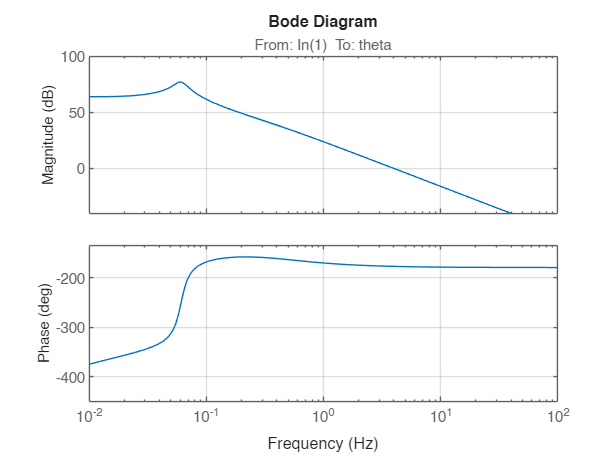

figure;
bp_pi = bodeplot(P_pitch * W1_long_att);
bp_pi.FrequencyUnit = 'Hz';
bp_pi.XLimits = [1e-2 1e2];
hold off
grid on

Shaped plant margin: 
     GainMargin: 0.020090781477231
    GMFrequency: 0.369662709731600
    PhaseMargin: [1×0 double]
    PMFrequency: [1×0 double]
    DelayMargin: 0
    DMFrequency: Inf
         Stable: 1

NCFSYN margins: 
     GainMargin: [1.994228261111299e-17 0.001086033349661]
    GMFrequency: [0 0.372030293849908]
    PhaseMargin: [1×0 double]
    PMFrequency: [1×0 double]
    DelayMargin: 0
    DMFrequency: Inf
         Stable: 1

NCFSYN gamma value: 1.0041


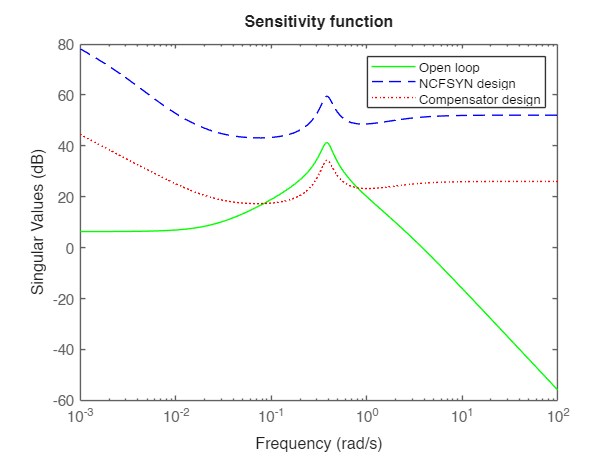

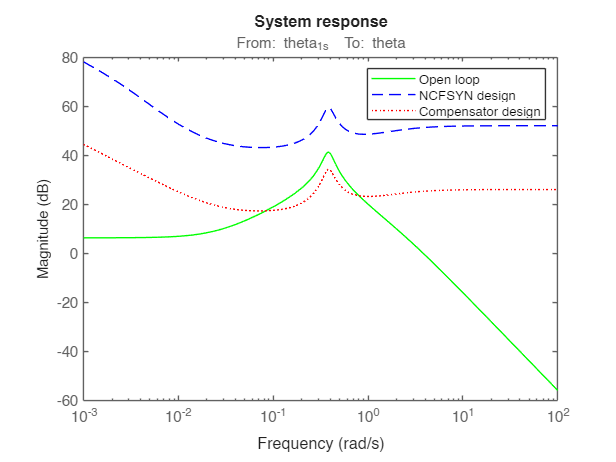

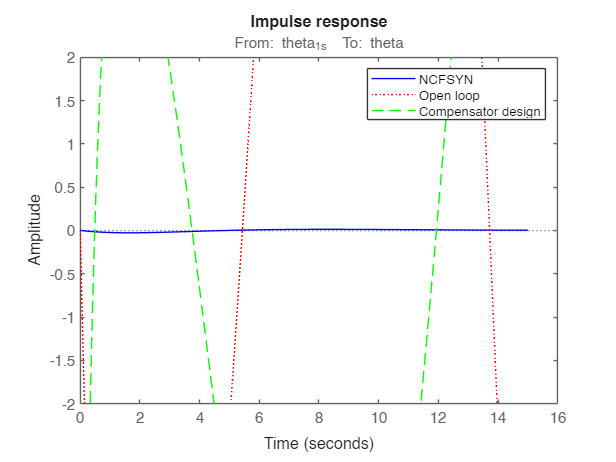

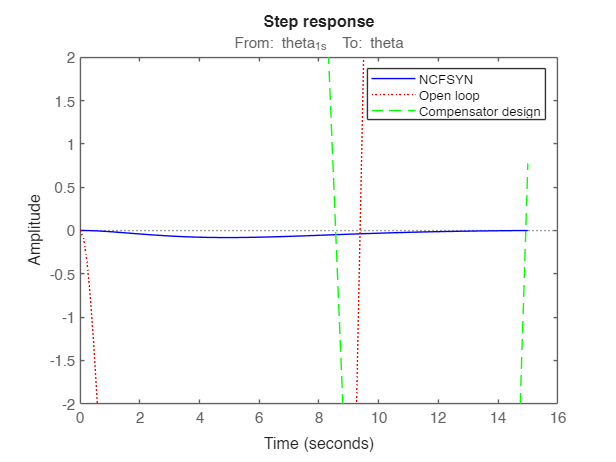


% W1_long_att = W1_pitch;  % W1_pitch is the pre-compensator weight proposed by Lanzon
% dc_gain = 13.1;
% W1_long_att = tf(dc_gain, [1, dc_gain/1000]);  % Low pass filter with high DC gain

% Post-compensator to reduce all gains
reduction = 30; 
% W2_long_att = ss(1);  % unity gain
% W2_long_att = W2_pitch;
W2_long_att = ss(10^(-reduction / 20));  % scalar reduction
% W2_long_att = tf(5, [1, 3]);  % low-pass filter

[K_long_att, ~, gam_long_att] = ncf_response(P_pitch, W1_long_att*Pitch_zero, W2_long_att);

W2_long_vel = 1;
[K_long_vel, ~, gam_long_vel] = ncf_response(P_uw, W1_long_vel, W2_long_vel);